# OGLO notebook 1

hnxj@github

## 1: Population iFR plots

RRRR

ifrm = cell(2, 10);
ifrs = cell(2, 10);

for k = 1:10

    ifrm{1, k} = zeros(areaCounts(k), 6000);
    ifrs{1, k} = zeros(areaCounts(k), 6000);
    ifrm{2, k} = zeros(areaCounts(k), 6000);
    ifrs{2, k} = zeros(areaCounts(k), 6000);

    ncount = 0;

    for l = 1:size(z{k}{1}, 2)

        ytm = squeeze(mean(z{k}{9}{l}, 1));
        yts = squeeze(std(z{k}{9}{l}, 1)) / sqrt(100);
        ytm(isnan(ytm)) = mean(ytm, 'all', 'omitnan');
        yts(isnan(yts)) = 0;

        N = min(size(ytm));

        ifrm{1, k}(ncount+1:ncount+N, :) = ytm;
        ifrs{1, k}(ncount+1:ncount+N, :) = yts;
        ncount = ncount + N;

    end

    ncount = 0;

    for l = 1:size(z{k}{1}, 2)

        ytm = squeeze(mean(z{k}{12}{l}, 1));
        yts = squeeze(std(z{k}{12}{l}, 1)) / sqrt(100);
        ytm(isnan(ytm)) = mean(ytm, 'all', 'omitnan');
        ytm(isnan(ytm)) = 0;
        yts(isnan(yts)) = 0;

        N = min(size(ytm));

        ifrm{2, k}(ncount+1:ncount+N, :) = ytm;
        try
            ifrs{2, k}(ncount+1:ncount+N, :) = yts;
        catch
            ifrs{2, k}(ncount+1:ncount+N, :) = 0;
        end
        ncount = ncount + N;

    end

    fprintf(num2str(k) + "-");

end

1-2-3-4-5-6-7-8-9-10-

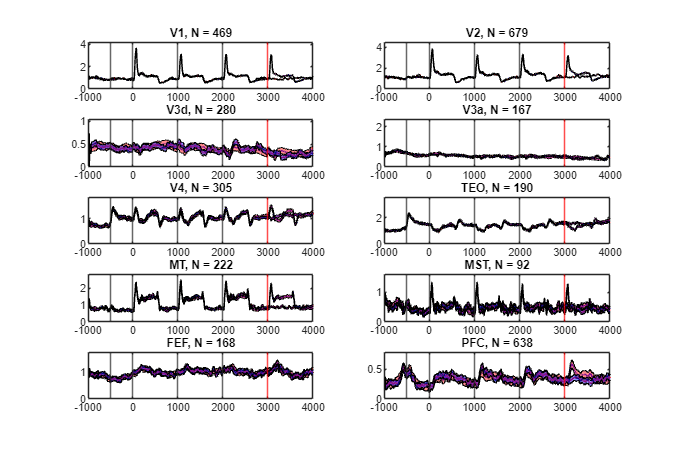

figure("Position", [0 0 1500 1000]);

t = linspace(-970, 4850, 6000);

for ik = 1:10

    subplot(5, 2, ik);

    % figure("Position", [0 0 1500 1000]);
    ksize = 50;

    if ik == 4 || ik == 3

        ksize = 150;

    end

    ix1 = mean(ifrm{1, ik}, 1);
    ix2 = mean(ifrm{2, ik}, 1);

    ix1 = smooth(detrend(ix1'), ksize);
    ix2 = smooth(detrend(ix2'), ksize);

    is1 = smooth(mean(ifrs{1, ik}, 1), ksize*4) / 20;
    is2 = smooth(mean(ifrs{2, ik}, 1), ksize*4) / 20;
    baselinem = - min((ix1 + ix2));

    sth1 = ix1 + is1 + baselinem;
    stl1 = ix1 - is1 + baselinem;
    sth2 = ix2 + is2 + baselinem;
    stl2 = ix2 - is2 + baselinem;
    
    plot(t, ix1 + baselinem, "b");hold("on");
    plot(t, ix2 + baselinem, "r");
    patch([t, t(end:-1:1)], [sth1;stl1(end:-1:1)], [1.0 0.1 0.1], "FaceAlpha", 0.5);
    patch([t, t(end:-1:1)], [sth2;stl2(end:-1:1)], [0.1 0.1 1.0], "FaceAlpha", 0.5);

    xline(-500);
    xline(0);
    xline(1000);
    xline(2000);
    xline(3000, "r");
    xlim([-1000 4000]);
    ylim([0 max(sth1)*1.2]);
    title(areaNames{ik} + ", N = " + num2str(areaCounts(ik)));

end


% sgtitle("Population iFR, AAAA(blue) AAAX(red)");

## End